# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** :**

**학번**** :**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

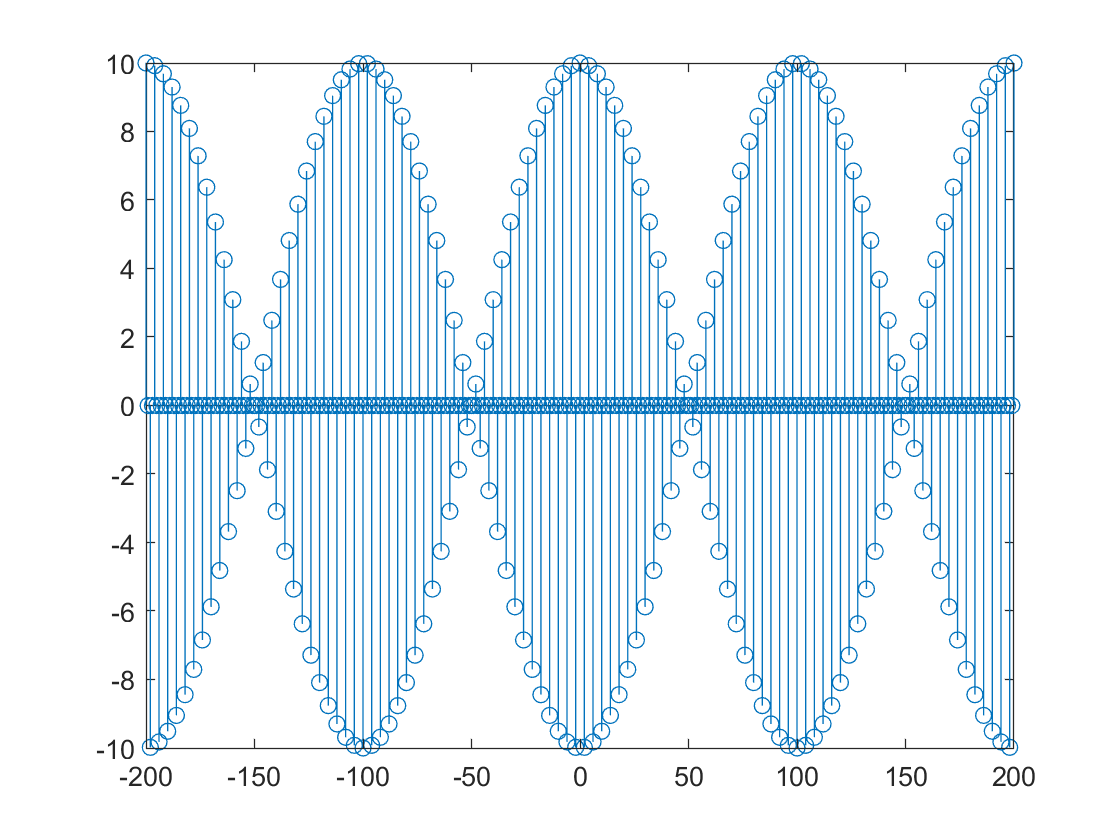

n = [-200:200];
x = 5*((cos(0.49*pi*n) + (cos(0.51*pi*n))));
stem(n,x);

2) 

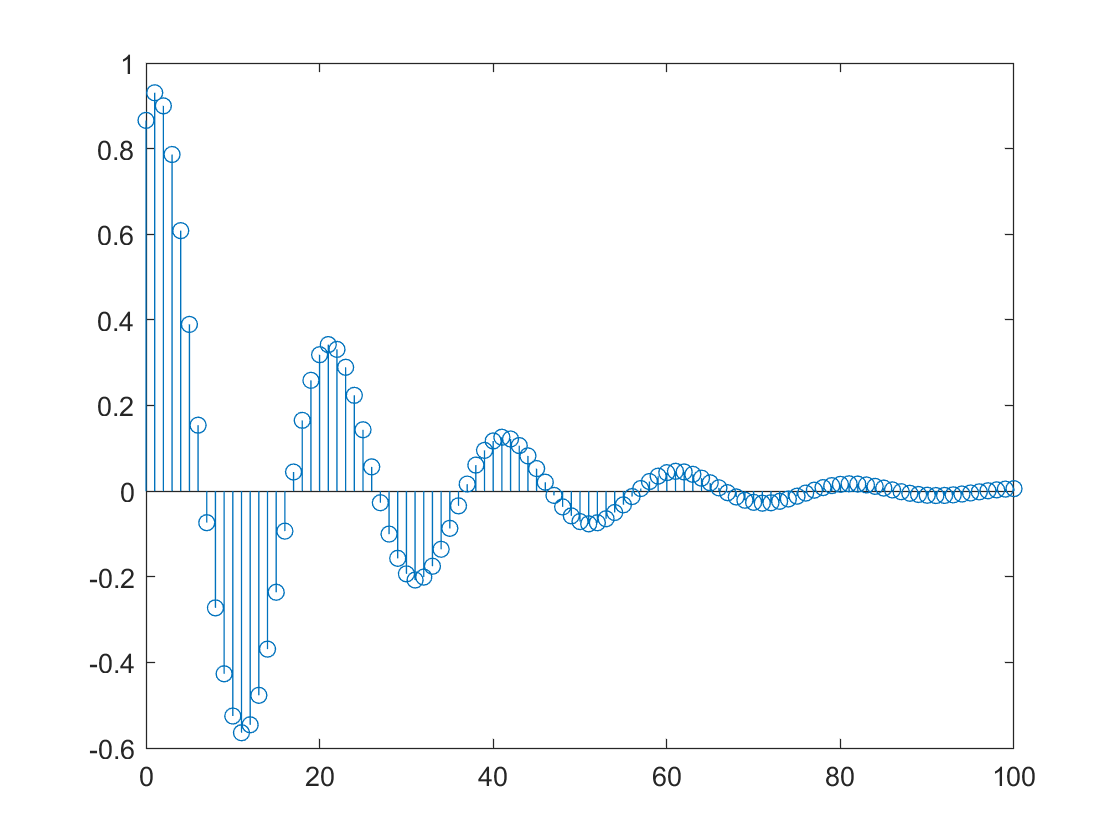


n = [0:100];
x = exp(-0.05*n).*((sin(0.1*pi*n + pi/3)));
stem(n,x);

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

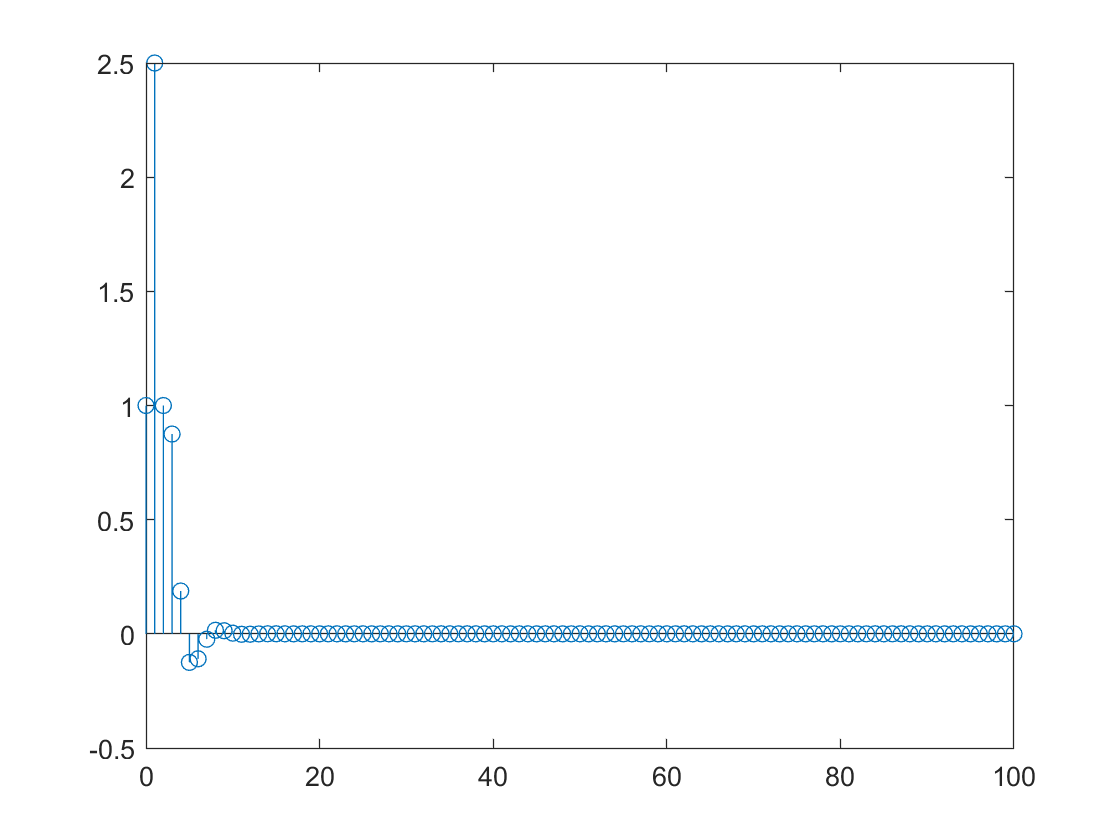

b= [1,2,0,1]; a = [1,-0.5,0.25]; n = [0:100];
h = impz(b,a,n);
stem(n,h)

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

stable = isinf(sum(abs(h)));

if (stable == 1)    
    disp('불안정한 시스템입니다.')
else 
    disp('안정한 시스템입니다.')
end

안정한 시스템입니다.


3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

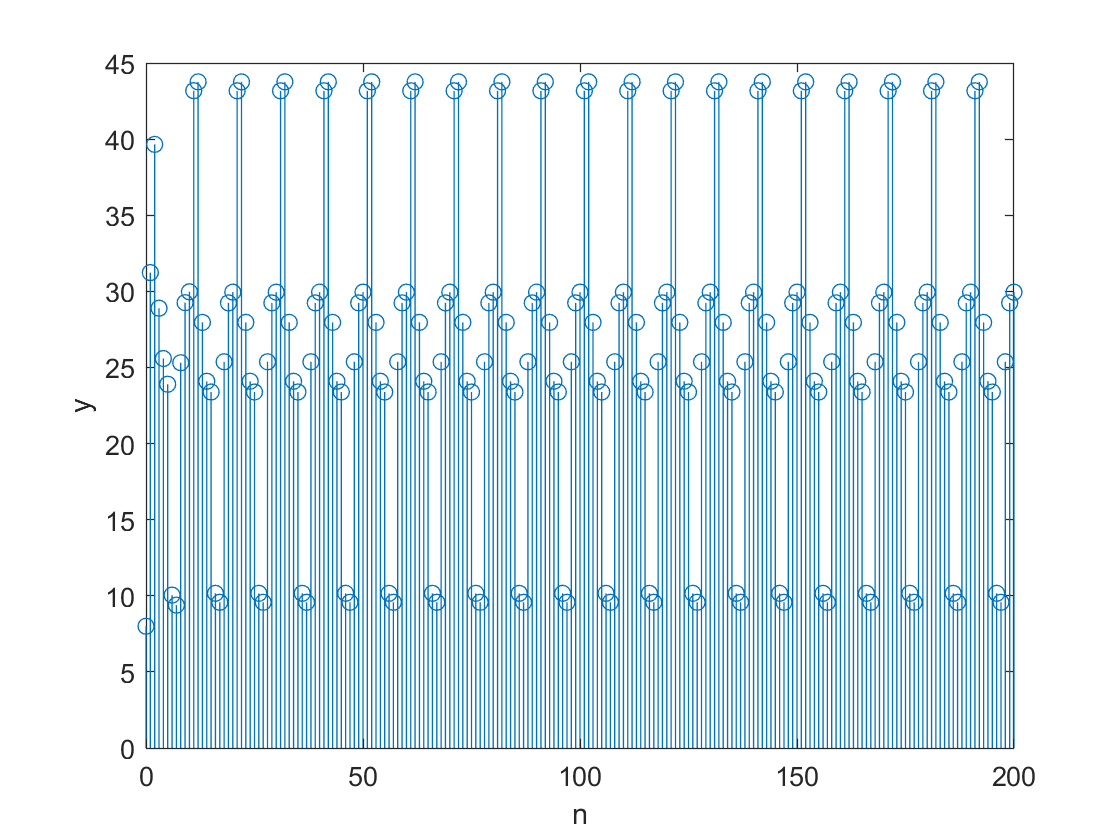

n = 0:200;
x = 5 + 3*cos(0.2*pi*n) + 4*sin(0.6*pi*n);
y = filter(b,a,x);
stem(n,y)
xlabel('n');
ylabel('y');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n = [0:25]

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


x = (0.8).^n

x =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352    0.0281    0.0225    0.0180    0.0144    0.0115    0.0092    0.0074    0.0059    0.0047    0.0038


h = (-0.9).^n

h =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718


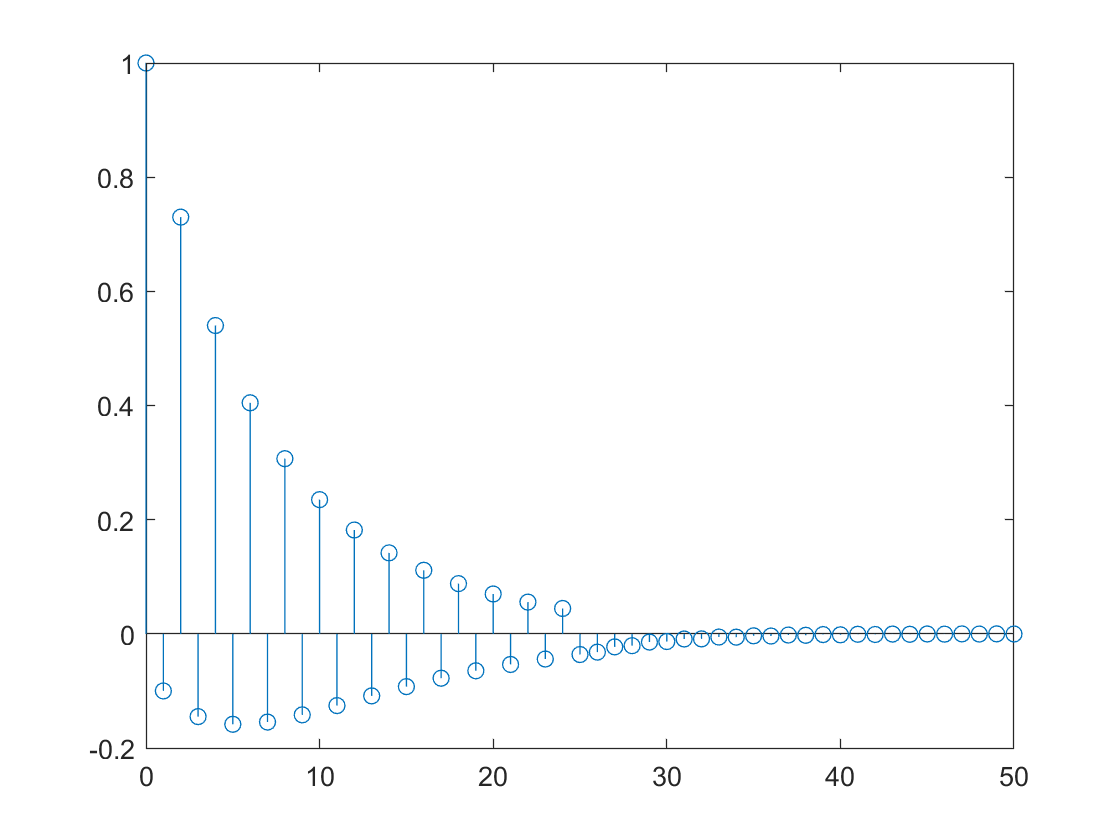

y = conv(x,h);

n1 = [0:50];
stem(n1,y);

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n = [0:25]

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


x = (0.8).^n

x =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352    0.0281    0.0225    0.0180    0.0144    0.0115    0.0092    0.0074    0.0059    0.0047    0.0038


h = (-0.9).^n

h =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718


y = conv(x,h);

n1 = [0:50];
stem(n1,y);

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

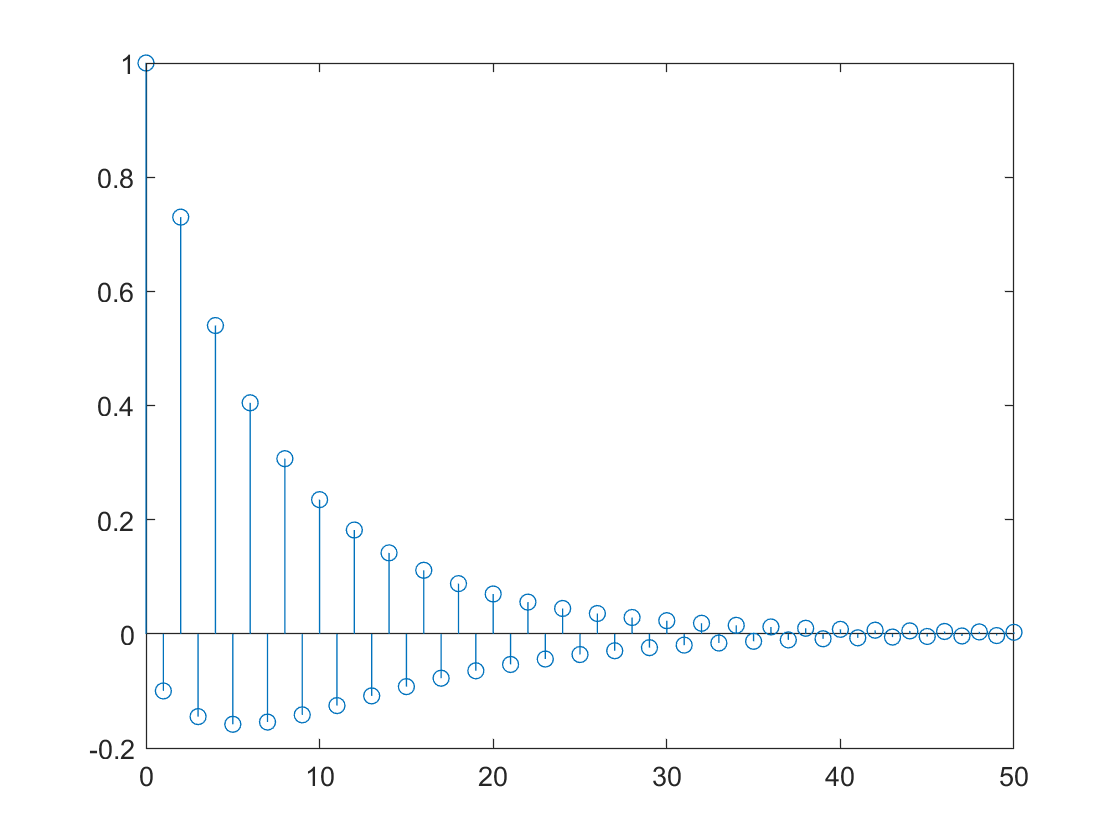

a = [1,-0.8];
b= [1];
n = 0:50;
x = (-0.9).^n;
y = filter(b,a,x);
stem(n,y);

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$


w = [-500:-1]*pi/499;
w2 = [1:500]*pi/499;
h = ((1 ./ (1 - 0.9*exp(j*w)) + 0.9 + (1 ./ (1 - 0.9*exp(-j*w2))) ));
magH = abs(h);
angH = angle(h);
subplot(2,1,1);
plot(w/pi,magH);

subplot(2,1,2);
plot(w/pi,angH/pi);

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

w = [-500:500]*pi/500;
h = exp(j*w) ./ (exp(j*w) - 0.5) + exp(j*w) ./ (exp(j*w) - 0.4);
magH = abs(h);
angH = angle(h);
subplot(2,1,1);
plot(w/pi,magH);
subplot(2,1,2);
plot(w/pi,angH/pi);


5. (P3.17) 

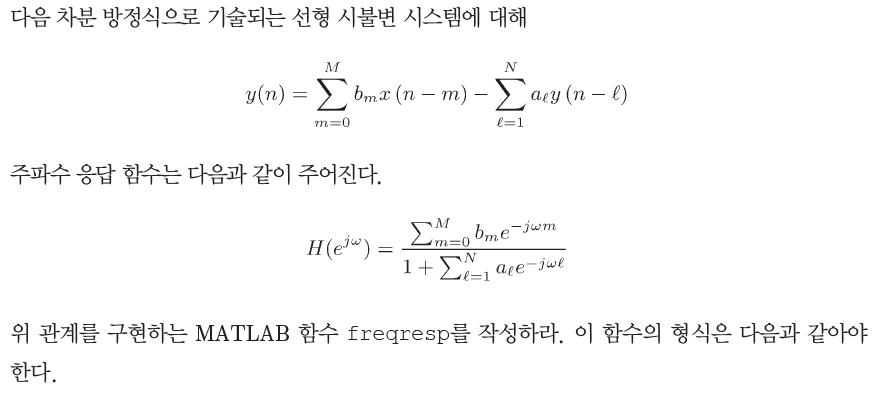

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

w = [-500:500] * pi/500

w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


h = (1-(0.9)*(0.9))./(1-0.9*2*cos(w)+(0.9)*(0.9));
magH = abs(h);
angH = angle(h);
subplot(2,1,1);
plot(w/pi,magH);
subplot(2,1,2);
plot(w/pi,angH/pi);



2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

w = [-500:500] * pi/500

w =    -3.1416   -3.1353   -3.1290   -3.1227   -3.1165   -3.1102   -3.1039   -3.0976   -3.0913   -3.0850   -3.0788   -3.0725   -3.0662   -3.0599   -3.0536   -3.0473   -3.0411   -3.0348   -3.0285   -3.0222   -3.0159   -3.0096   -3.0034   -2.9971   -2.9908   -2.9845   -2.9782   -2.9719   -2.9657   -2.9594   -2.9531   -2.9468   -2.9405   -2.9342   -2.9280   -2.9217   -2.9154   -2.9091   -2.9028   -2.8965   -2.8903   -2.8840   -2.8777   -2.8714   -2.8651   -2.8588   -2.8526   -2.8463   -2.8400   -2.8337


n = 0:5;
a = (0.5).^n

a =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0312


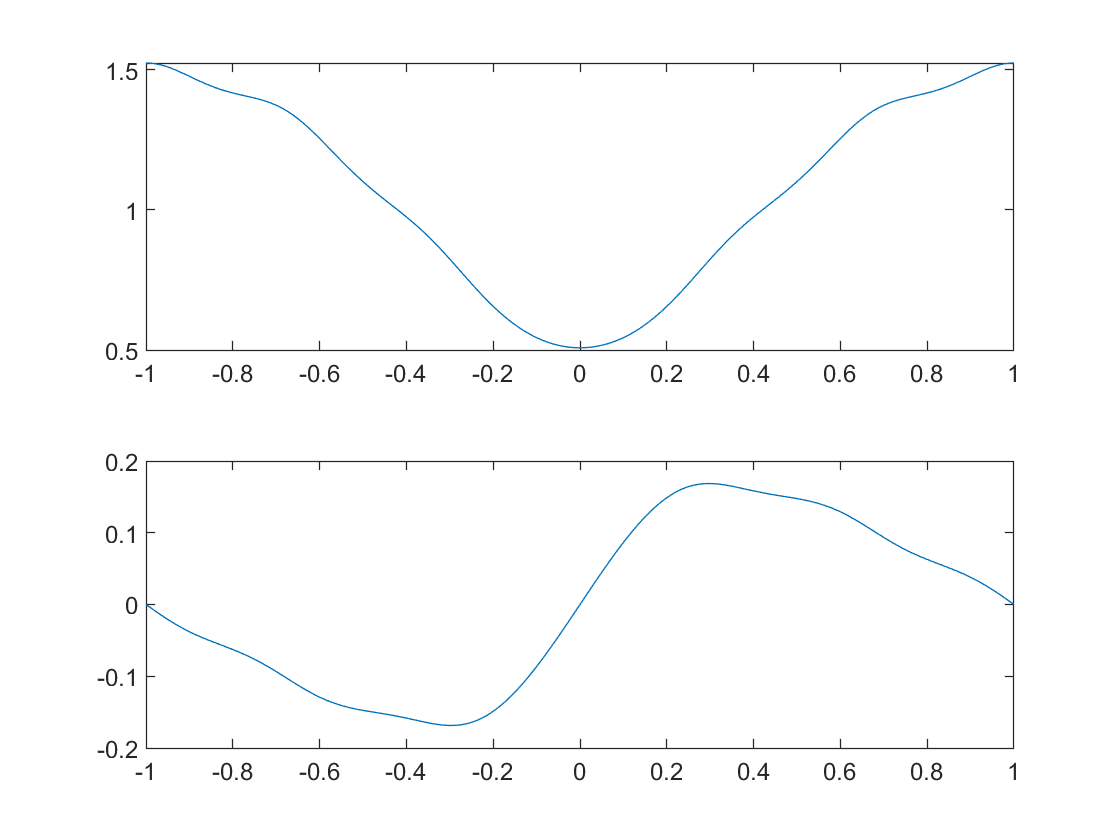

b = [1];
m = 0:length(b)-1;
l = 0:length(a)-1;
num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
H = num./den;
magH = abs(H);
angH = angle(H);
subplot(2,1,1);
plot(w/pi,magH);
subplot(2,1,2);
plot(w/pi,angH/pi);

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
m = 0:length(b)-1;
l = 0:length(a)-1;
num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
[H] = num./(1+den);
end